# 需求分析：Matlab libsvm 工具箱安装和使用

## libsvm 下载和安装：

- libsvm 下载链接：[https://www.csie.ntu.edu.tw/~cjlin/libsvm/#download](https://www.csie.ntu.edu.tw/~cjlin/libsvm/#download)

- libsvm 使用：解压之后放到常用目录，然后设置路径，选择 matlab 文件夹运行 make.m 文件，编译成功即可使用

## 测试说明：

- 拷贝 heart_scale 文件到当前目录

- 参数说明

## 测试代码：

clear;clc;close all;
% 加载数据
[heart_scale_label, heart_scale_inst] = libsvmread('heart_scale');
% 稀疏矩阵转一般形式
heart_scale_inst = full(heart_scale_inst);
% 训练集数量
train_number = 200;
% 训练集
train_label = heart_scale_label(1:train_number, :);
train_inst = heart_scale_inst(1:train_number, :); 
test_label = heart_scale_label(train_number+1:end, :);
test_inst = heart_scale_inst(train_number+1:end, :);
% 训练
cmd = '-s 3 -t 2 -c 0.1 -g 0.1 -p 0.1';
model = svmtrain(train_label, train_inst, cmd); %#ok<SVMTRAIN> 

*
optimization finished, #iter = 93
nu = 0.776556
obj = -10.942120, rho = 0.048525
nSV = 159, nBSV = 151


% 训练结果
predict_train_label = svmpredict(train_label, train_inst, model);

Mean squared error = 0.474862 (regression)
Squared correlation coefficient = 0.523051 (regression)


% 测试结果
[predict_label, accuracy, decision_values] = svmpredict(test_label, test_inst, model);

Mean squared error = 0.50495 (regression)
Squared correlation coefficient = 0.48877 (regression)


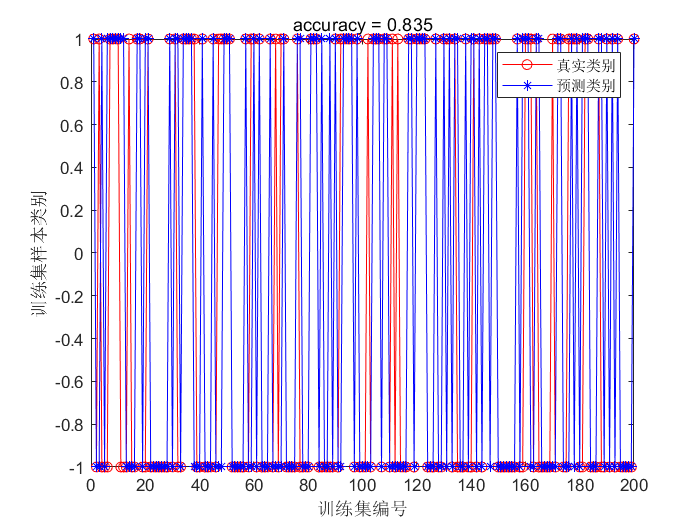

% 标签只有两个类别
predict_train_label(predict_train_label < 0) = -1;
predict_train_label(predict_train_label > 0) = 1;
predict_label(predict_label < 0) = -1;
predict_label(predict_label > 0) = 1;
accu1 = sum(predict_train_label == train_label) / length(train_label);
accu2 = sum(predict_label == test_label) / length(test_label);
% 画图
figure
plot(train_label, '-ro');
hold on
plot(predict_train_label, '-b*');
hold off
xlabel('训练集编号');
ylabel('训练集样本类别');
title(['accuracy = ', num2str(accu1)]);
legend('真实类别', '预测类别');

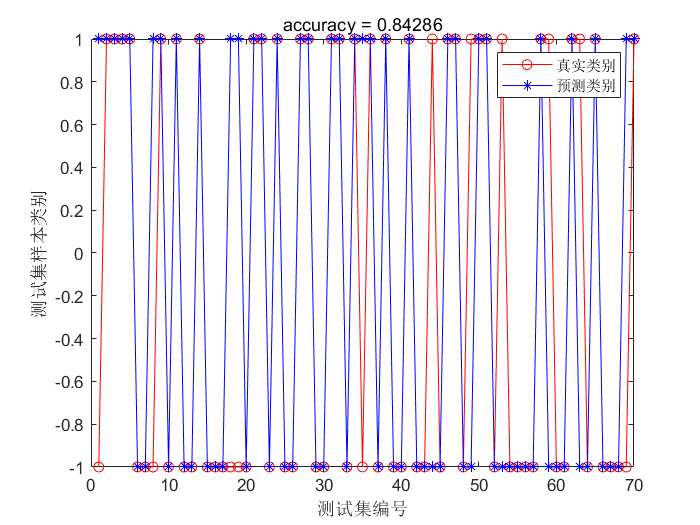

figure
plot(test_label, '-ro');
hold on
plot(predict_label, '-b*');
hold off
xlabel('测试集编号');
ylabel('测试集样本类别');
title(['accuracy = ', num2str(accu2)]);
legend('真实类别', '预测类别');

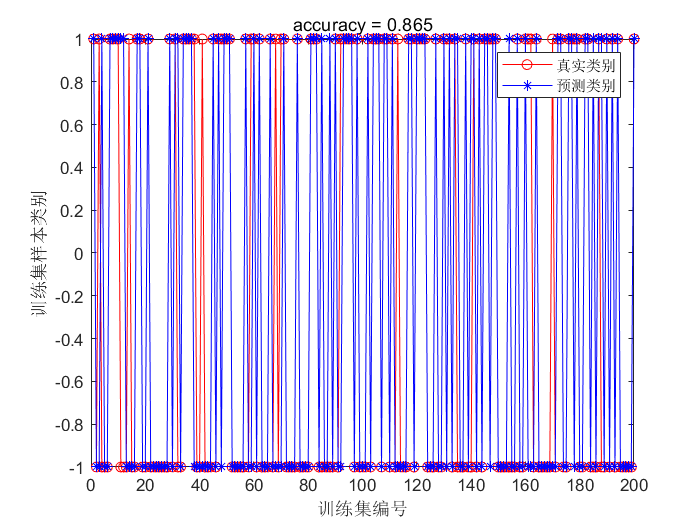

% 用自带函数来测试一下结果
% 训练
SVMModel = fitcsvm(train_inst, train_label);
% 训练结果
label1 = predict(SVMModel, train_inst);
% 测试结果
label2 = predict(SVMModel, test_inst);
accu3 = sum(label1 == train_label) / length(train_label);
accu4 = sum(label2 == test_label) / length(test_label);
% 画图
figure
plot(train_label, '-ro');
hold on
plot(label1, '-b*');
hold off
xlabel('训练集编号');
ylabel('训练集样本类别');
title(['accuracy = ', num2str(accu3)]);
legend('真实类别', '预测类别');

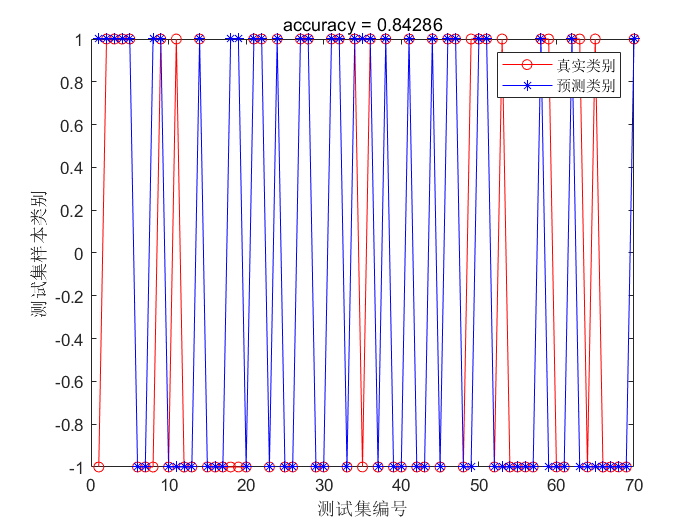

figure
plot(test_label, '-ro');
hold on
plot(label2, '-b*');
hold off
xlabel('测试集编号');
ylabel('测试集样本类别');
title(['accuracy = ', num2str(accu4)]);
legend('真实类别', '预测类别');